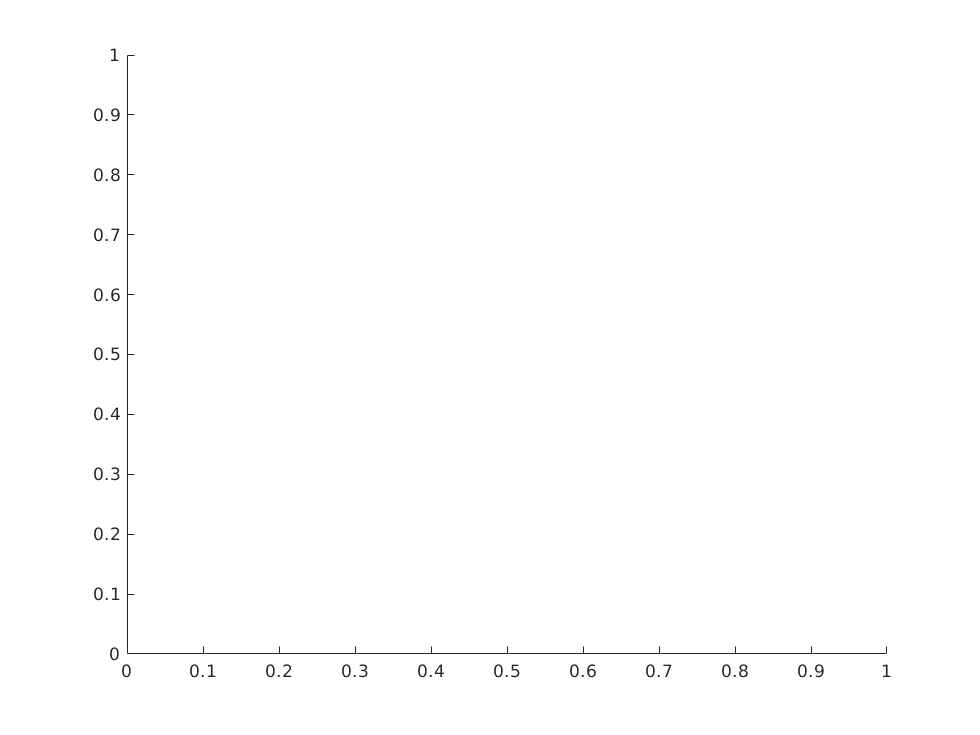

clear
clf
clc
load("pcla0340_20o.mea");
hold off

time = [86400]

time = 86400

numVisibleSats = [0]

numVisibleSats = 0

for i = 1:length(pcla0340_20o)
    if pcla0340_20o(i,1) == time(end)
        numVisibleSats(end) = numVisibleSats(end)+1;
    else
        time = [time,pcla0340_20o(i,1)];
        numVisibleSats = [numVisibleSats,1];
    end
end



%figure
%plot(time,numVisibleSats)
%plot(time/60/60 -24, numVisibleSats)

%3
prns = zeros(length(time),32);
CAranges = zeros(length(time),32);
CAphases = zeros(length(time),32);
L1Doppler = zeros(length(time),32);
L2CarrierPhase = zeros(length(time),32);
L2Prange = zeros(length(time),32);
for i = 1:length(pcla0340_20o)
    timeindex = 1+(pcla0340_20o(i,1)-86400)/15;
    prn = pcla0340_20o(i,2);
    prns(timeindex,prn) = prn;
    CAranges(timeindex,prn) = pcla0340_20o(i,3);
    CAphases(timeindex,prn) = pcla0340_20o(i,5);
    L1Doppler(timeindex,prn) = pcla0340_20o(i,6);
    L2CarrierPhase(timeindex,prn) = pcla0340_20o(i,10);
    L2Prange(timeindex,prn) = pcla0340_20o(i,9);
end
timeinday = (0:15:86385)/60/60

timeinday =          0    0.0042    0.0083    0.0125    0.0167    0.0208    0.0250    0.0292    0.0333    0.0375    0.0417    0.0458    0.0500    0.0542    0.0583    0.0625    0.0667    0.0708    0.0750    0.0792    0.0833    0.0875    0.0917    0.0958    0.1000    0.1042    0.1083    0.1125    0.1167    0.1208    0.1250    0.1292    0.1333    0.1375    0.1417    0.1458    0.1500    0.1542    0.1583    0.1625    0.1667    0.1708    0.1750    0.1792    0.1833    0.1875    0.1917    0.1958    0.2000    0.2042


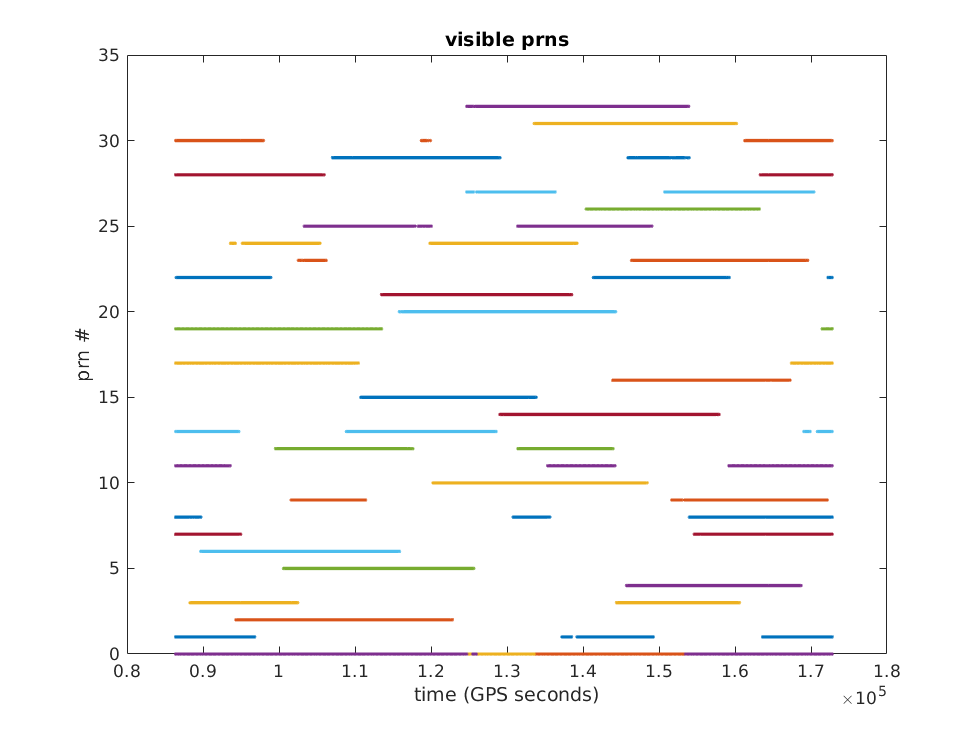

figure
plot(timeinday*3600+86400,prns,'.')
title("visible prns")
xlabel("time (GPS seconds)")
ylabel("prn #")

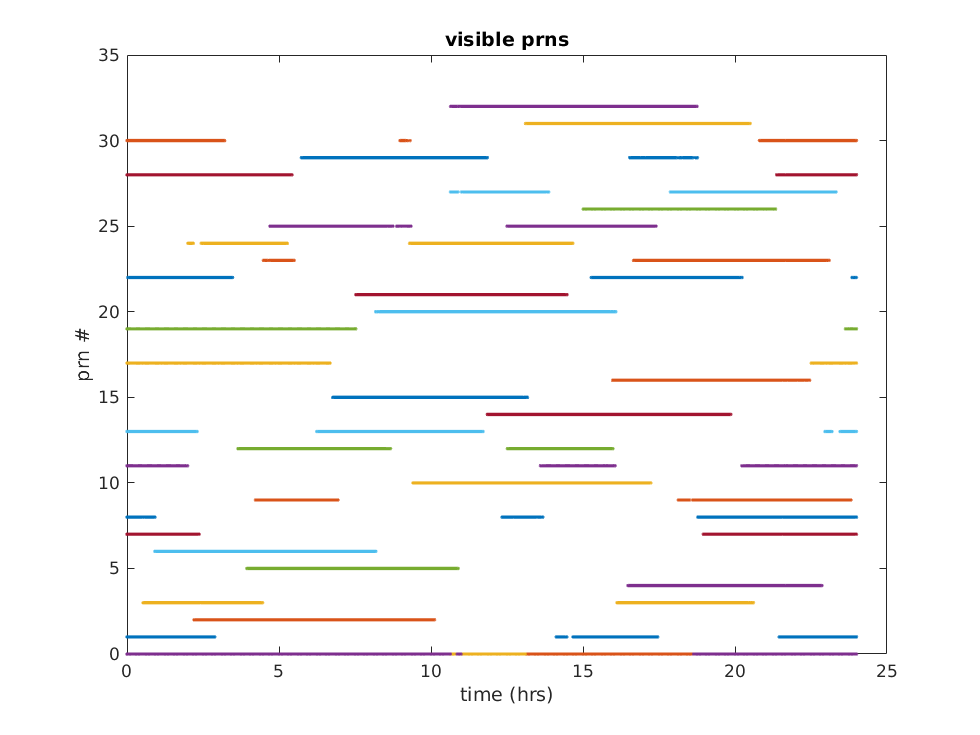


figure
plot(timeinday,prns,'.')
title("visible prns")
xlabel("time (hrs)")
ylabel("prn #")

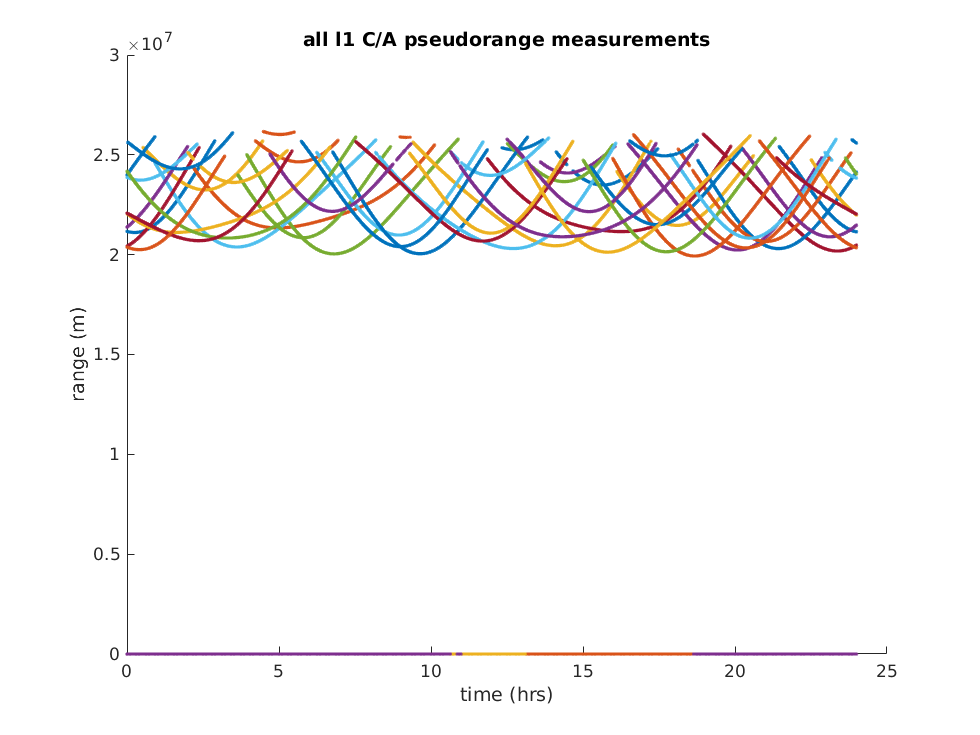


figure
hold on

plot(timeinday,CAranges,'.')
title("all l1 C/A pseudorange measurements")
xlabel("time (hrs)")
ylabel("range (m)")

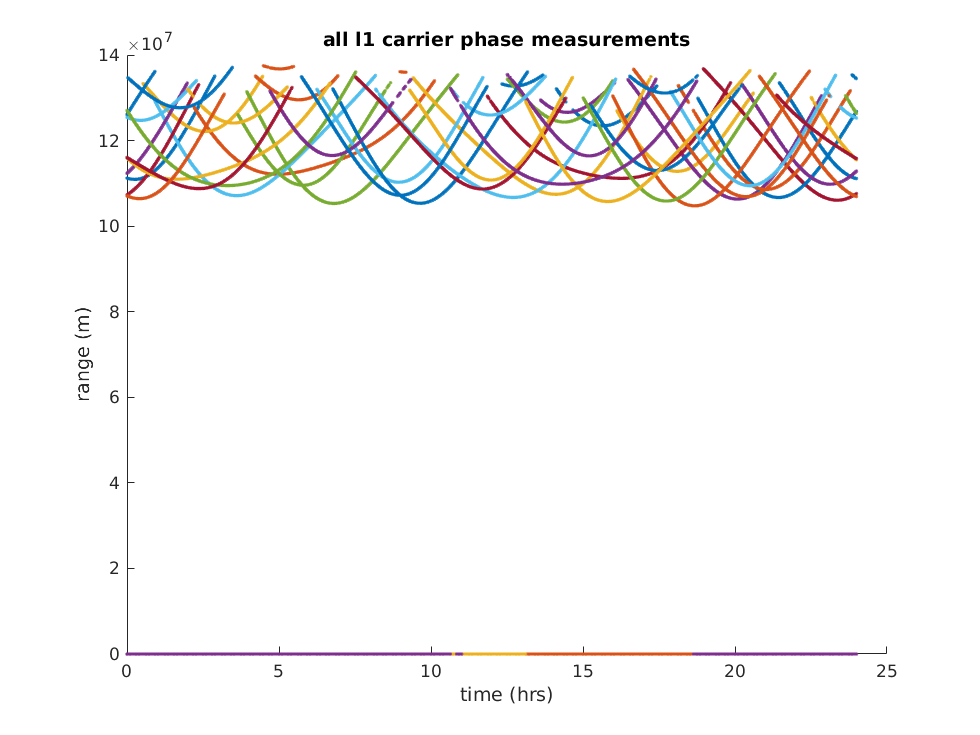


%4
figure
hold on
plot(timeinday,CAphases,'.')

title("all l1 carrier phase measurements")
xlabel("time (hrs)")
ylabel("range (m)")

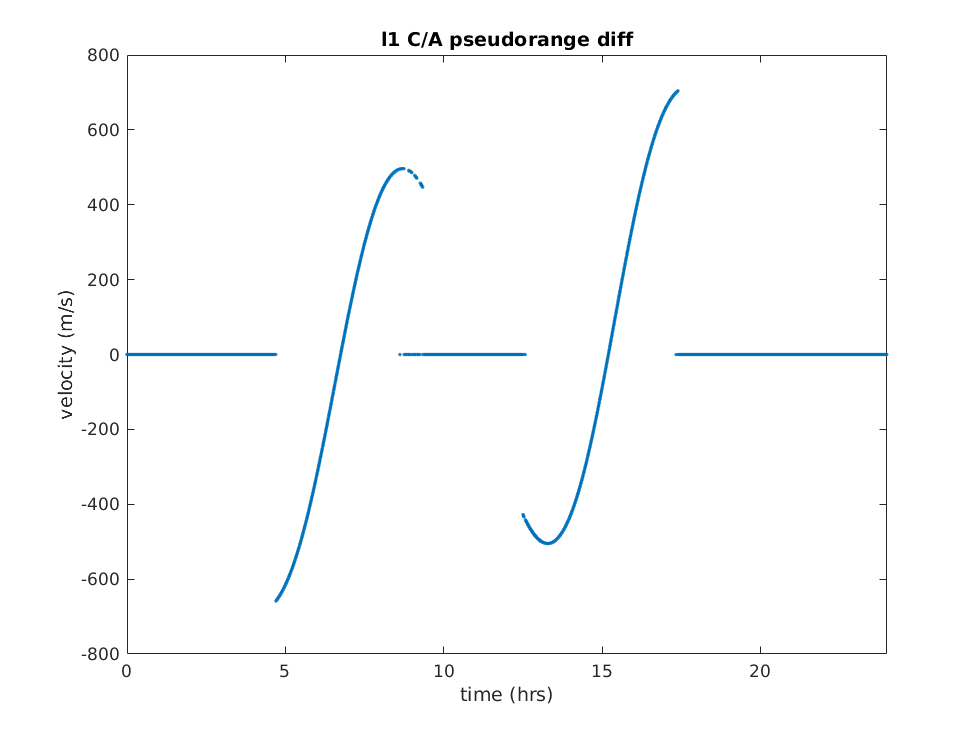

%5
satPrn = 25;
figure
plot(timeinday(1:end-1),diff(CAranges(:,satPrn))/15,'.')
axis([0 24 -800 800])
title("l1 C/A pseudorange diff")
xlabel("time (hrs)")
ylabel("velocity (m/s)")

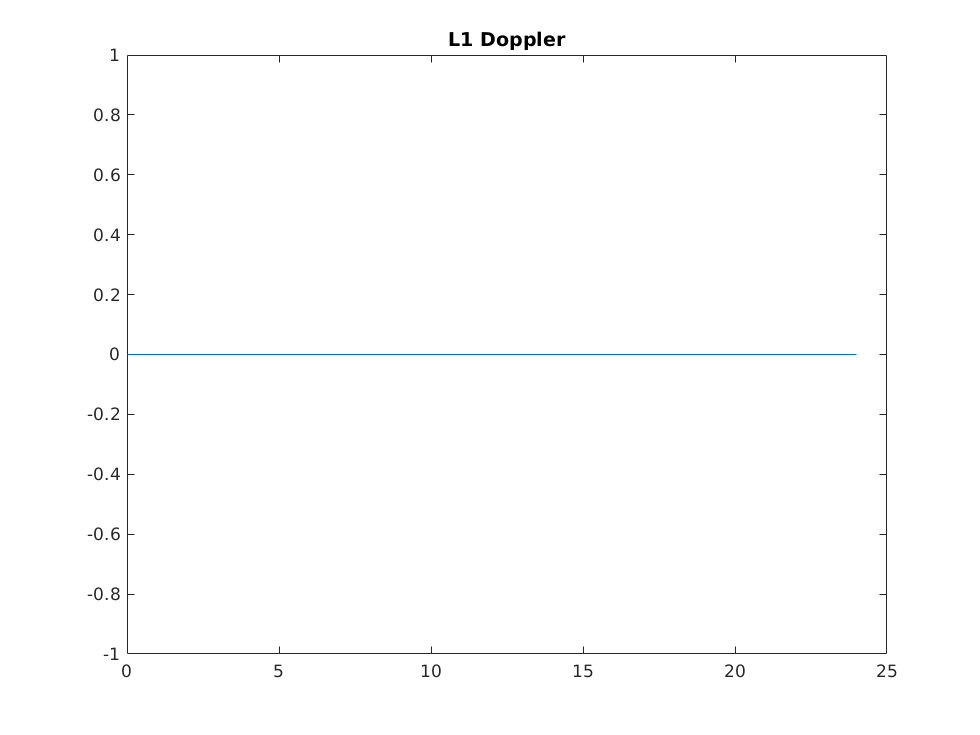

%6
figure
plot(timeinday,L1Doppler(:,satPrn))
title("L1 Doppler")

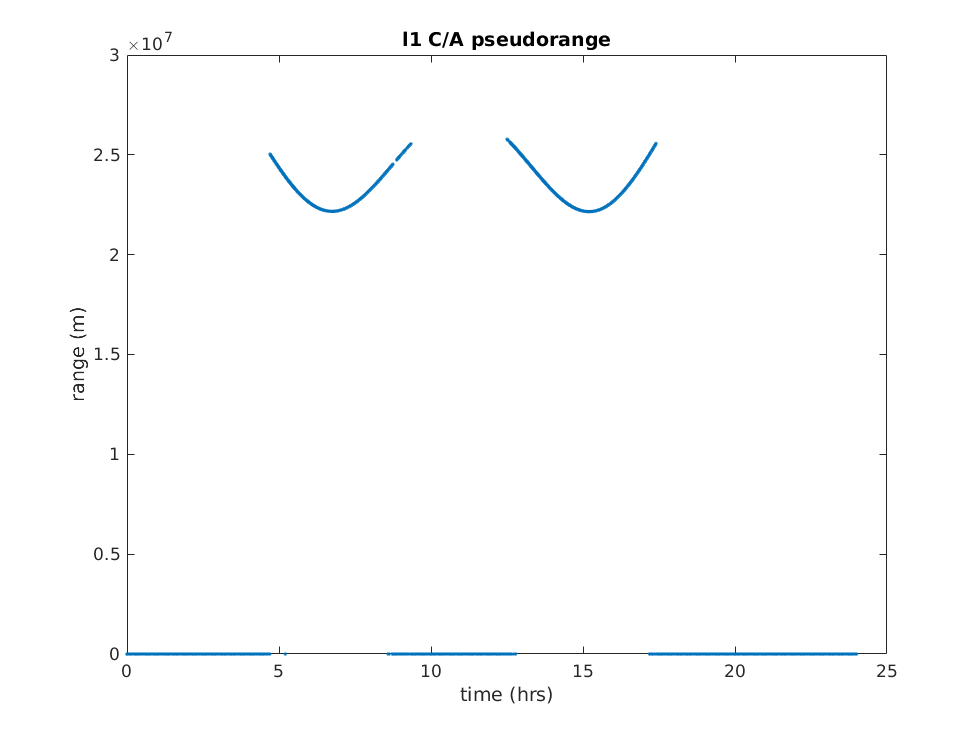

%7
figure 
plot(timeinday,CAranges(:,satPrn),'.')
title("l1 C/A pseudorange")
xlabel("time (hrs)")
ylabel("range (m)")

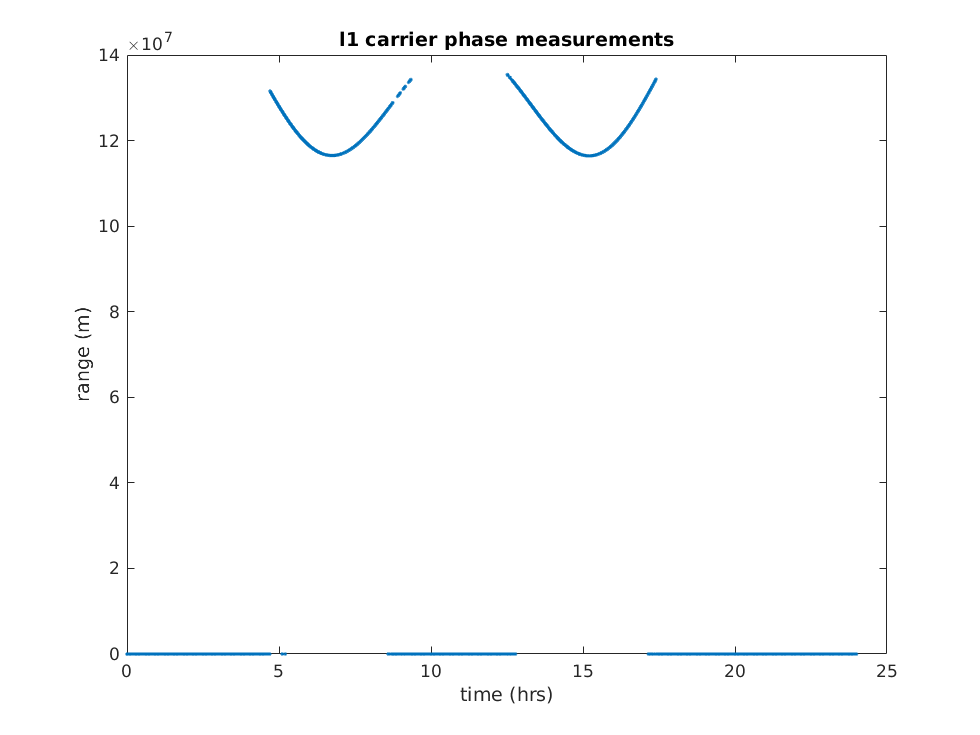

%8
figure
plot(timeinday,CAphases(:,satPrn),'.')
title("l1 carrier phase measurements")
xlabel("time (hrs)")
ylabel("range (m)")

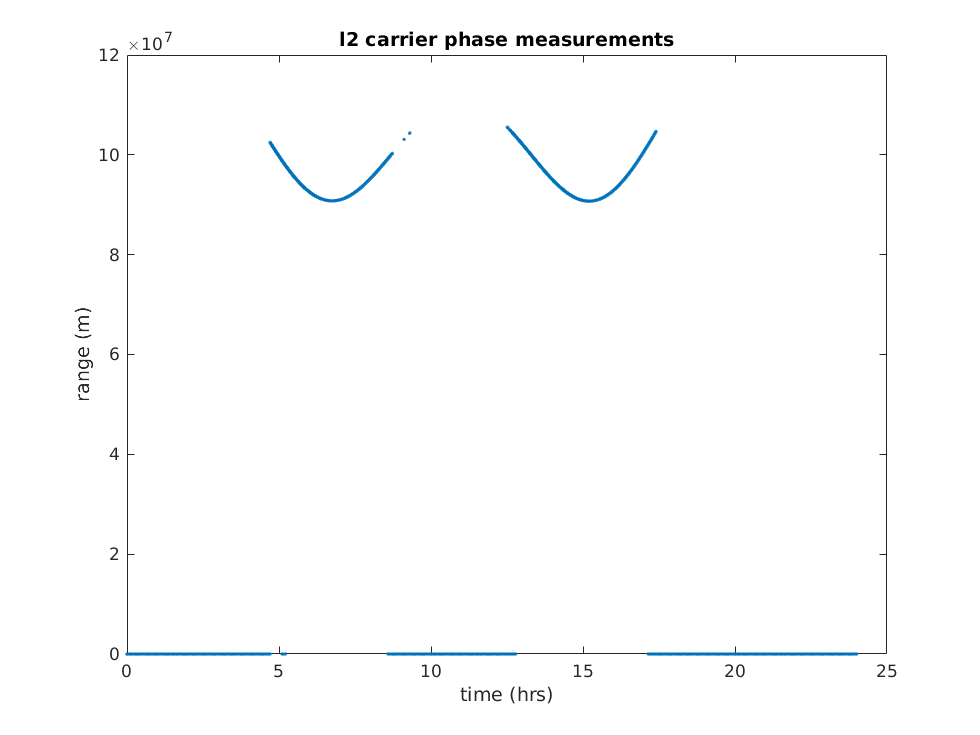

%9
figure
plot(timeinday,L2CarrierPhase(:,satPrn),'.')
title("l2 carrier phase measurements")
xlabel("time (hrs)")
ylabel("range (m)")

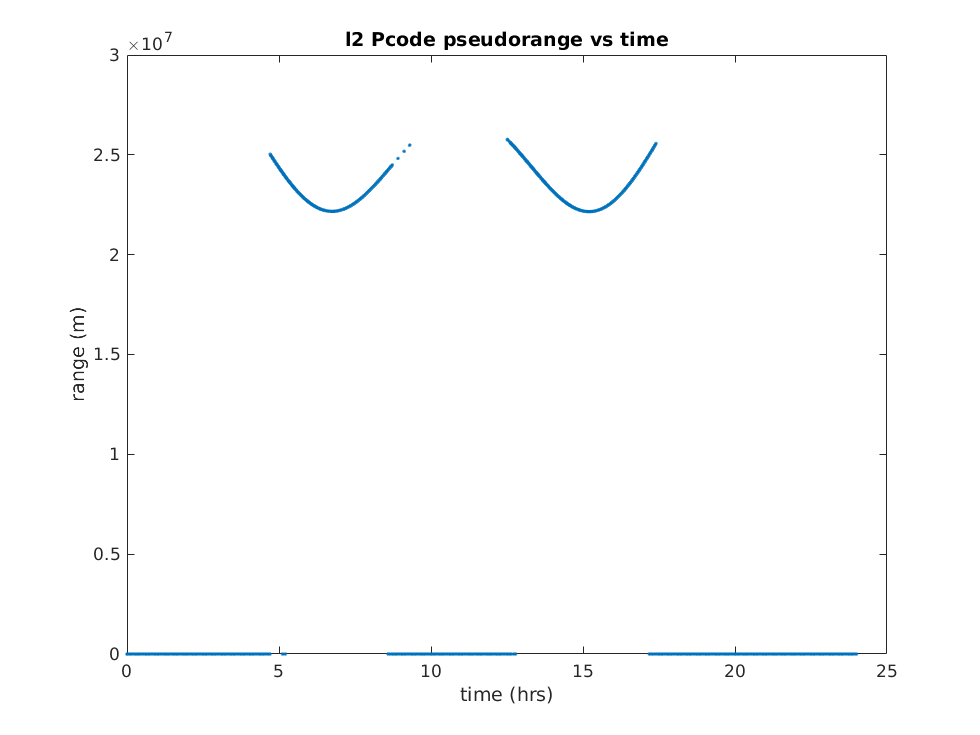

%10
figure
plot(timeinday,L2Prange(:,satPrn),'.');
title("l2 Pcode pseudorange vs time")
xlabel("time (hrs)")
ylabel("range (m)")

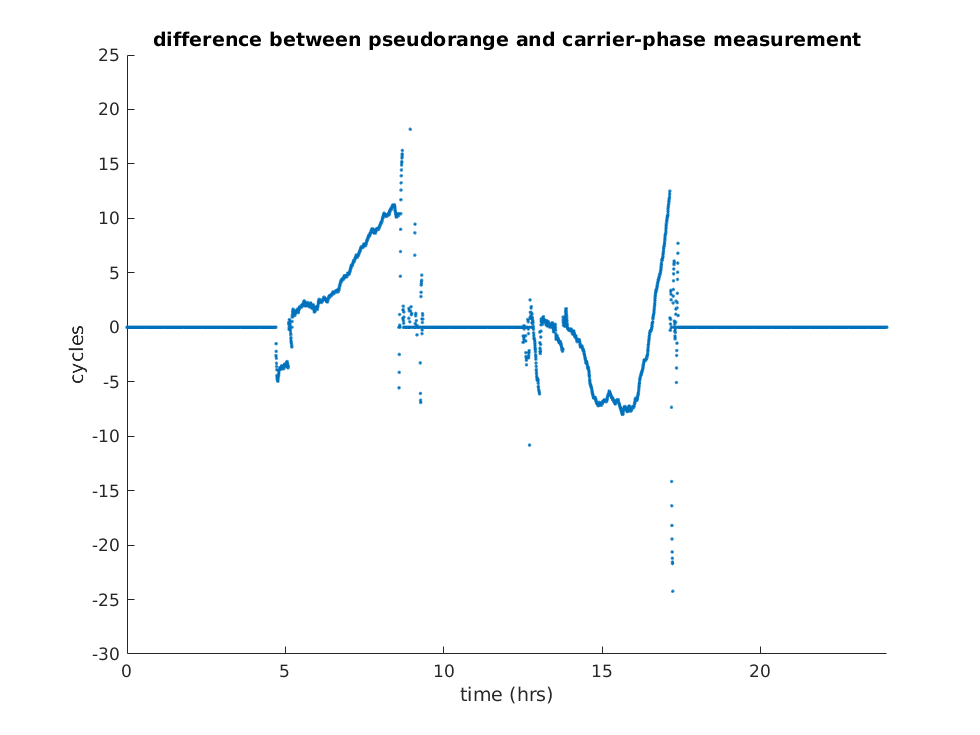

%11
figure
hold on
c=299792458;
plot(timeinday,CAranges(:,satPrn)*1575.42e6/c-CAphases(:,satPrn),'.')
axis([0 24 -30 25])
title("difference between pseudorange and carrier-phase measurement")
xlabel("time (hrs)")
ylabel("cycles")

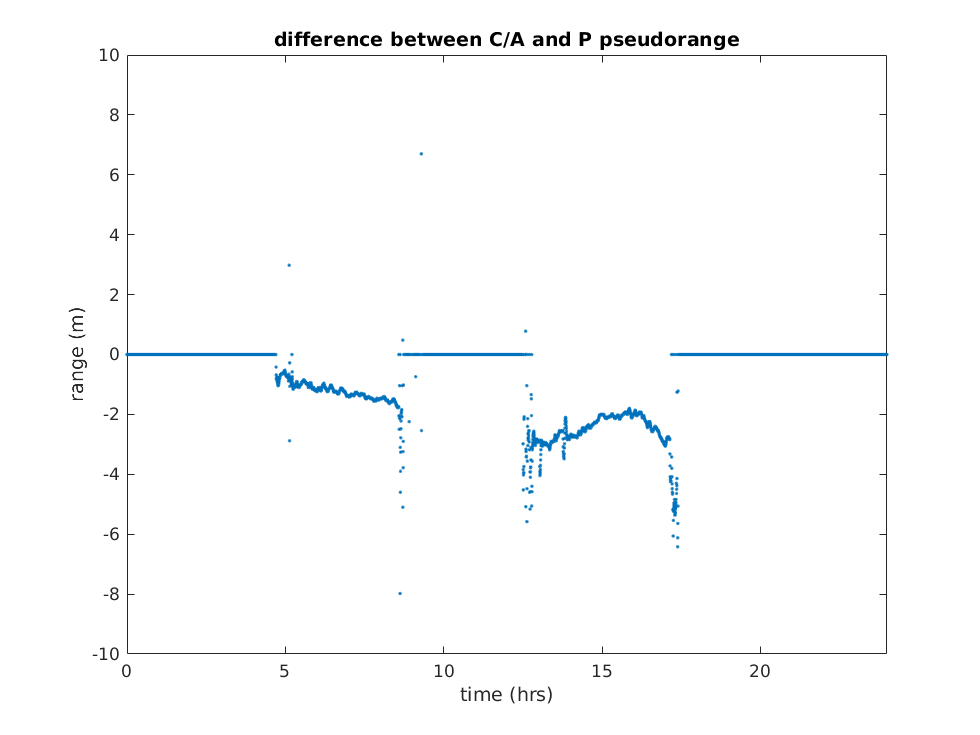

figure
plot(timeinday,CAranges(:,satPrn)-L2Prange(:,satPrn),'.')
axis([0 24 -10 10])
title("difference between C/A and P pseudorange")
xlabel("time (hrs)")
ylabel("range (m)")

A. There is on average a 3 meter difference between the L1 C/A code pseudorange and the L2 P code pseudorange

B. There can be up to a 10 meter difference between the carrier phase measurement and the pseudorange. A cycle slip happens at 5.2 hours 

C. Based on the velocity plot, satellite ranges from travelling towards the receiver at 658 m/s to travelling away at 704 m/s

length(unique(pcla0340_20o(:,2)))

ans = 31

D. 31 satellites were visible throughout the day. Satellite 18 was not seen

%Ohio data
load("ohdt0340.mea");
%alaska data
load("brw10340.mea");


ohprns = zeros(length(timeinday),32);
for i = 1:length(ohdt0340)
    timeindex = 1+(ohdt0340(i,1)-86400)/15;
    prn = ohdt0340(i,2);
    ohprns(timeindex,prn) = prn;
end
akprns = zeros(length(timeinday),32);
for i = 1:length(brw10340)
    timeindex = 1+(brw10340(i,1)-86400)/15;
    prn = brw10340(i,2);
    akprns(timeindex,prn) = prn;
end

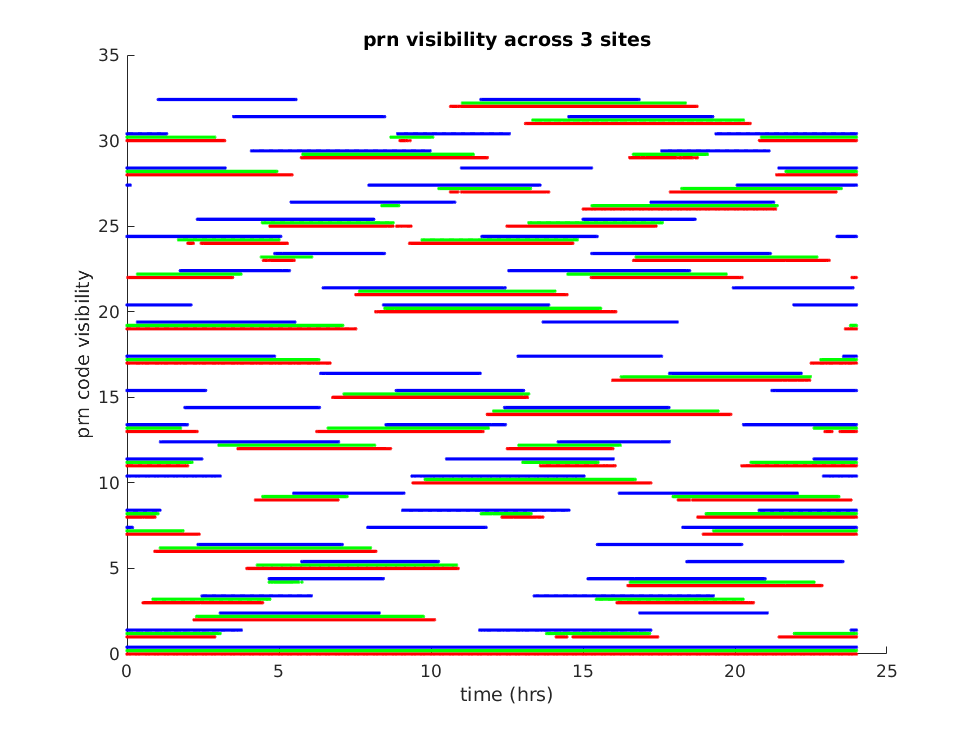


figure
hold on
plot(timeinday,prns,'r.')
plot(timeinday,ohprns+0.2,'g.')
plot(timeinday,akprns+0.4,'b.')
title("prn visibility across 3 sites")
xlabel("time (hrs)")
ylabel("prn code visibility")

At higher latitudes, the satellites are visible for less time but they are visible more frequently. the Florida and Ohio stations correlate fairly well while the alaska station reads completely differently.